# Developer documentation: `Delta` objects

This documentation is targeted to developers who want to provide their own `Delta` and `MultiplierDelta` classes to further extend the expressive and analytical capabilities of `iqcToolbox`. The design structure for `Performance` and `Disturbance` classes is similar, and this documentation will also help developing those and related classes. After this script you will understand the architecture of `Delta` classes, the methods that must be implemented for a new `Delta` subclass, how `Delta` objects are grouped together in `SequenceDelta` classes, and how a new `MultiplierDelta` subclass must interact with a new  `Delta` subclass.

## Motivation for abstract classes and inheritance

To begin, `iqcToolbox` is built with a heavy reliance on *object-oriented programming (OOP)*, which leverages classes and inheritance to structure and implement the functionality of this toolbox.  If you are unfamiliar with OOP and how MATLAB approaches OOP, two good places to start are [here](https://www.mathworks.com/help/matlab/object-oriented-programming.html) and [here](https://www.mathworks.com/help/matlab/matlab_oop/user-defined-classes.html).

*Note:*

*For developers familiar with OOP but not MATLAB OOP: the typical OOP approach in MATLAB (and the approach followed in this toolbox) does not rely on references to objects. Syntax such as *`g_lft.addPerformance(...) `*does not modify the *`g_lft`* object, but outputs a new *`Ulft`* object with an added performance.*

In `iqcToolbox`, modeling and analysis is focused on a linear fraction transformation (LFT) of an uncertain and nonlinear system, annotated $(M, \Delta)$.

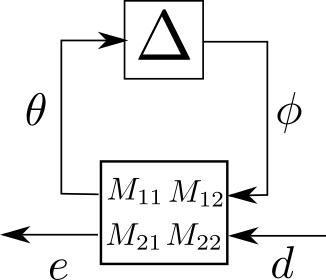

Typically, $\Delta$ represents a collection of different uncertainties, nonlinearities, and operators, which are all structured in a block diagon form: $\Delta = \mathrm{diag}(\Delta_1,  \Delta_2, ..., \Delta_N)$. For example, $\Delta_1$ might represent an uncertain parameter (such as mass) in the system's equations of motion, $\Delta_2$ might represent a nonlinear (but passive) friction force acting on the system, and so on. We see this structure in our `Ulft `class:

rng(4)
g_del = Ulft.random('num_deltas', 4);
g_del.delta

ans = ********************************************************************************
**********************************   DELTAS   **********************************
     ANWoKszIfA is a   1 x 10    DLTI uncertainty 
              whose hinf norm is less than: 4.4 
     xotJDfImVb is a   2 x 2   SLTV, rate-bounded uncertainty 
              within the bounds: [-5.2, 5.2] 
              whose rate-of-change is within: [-1.1, 1.1] 
     bhUhUgnJTa is a   6 x 6     SLTV uncertainty 
              within the bounds: [-2.5, 2.5] 
     guShJZJvWr is a   5 x 5     SLTI uncertainty 
              within the bounds: [-9.0, 9.0] 

Here we see a variety of different $\Delta$ objects: a dynamic linear time-invariant (DLTI) uncertainty, a static linear time-varying rate-bounded (SLTV-RB) uncertainty, an arbitrarily fast SLTV uncertainty, and so on. In order to allow a broad expression of different $\Delta$ sets (many of which may not be currently implemented or discovered), we structure each type of uncertainty/nonlinearity as a subclass of the abstract `Delta `class:

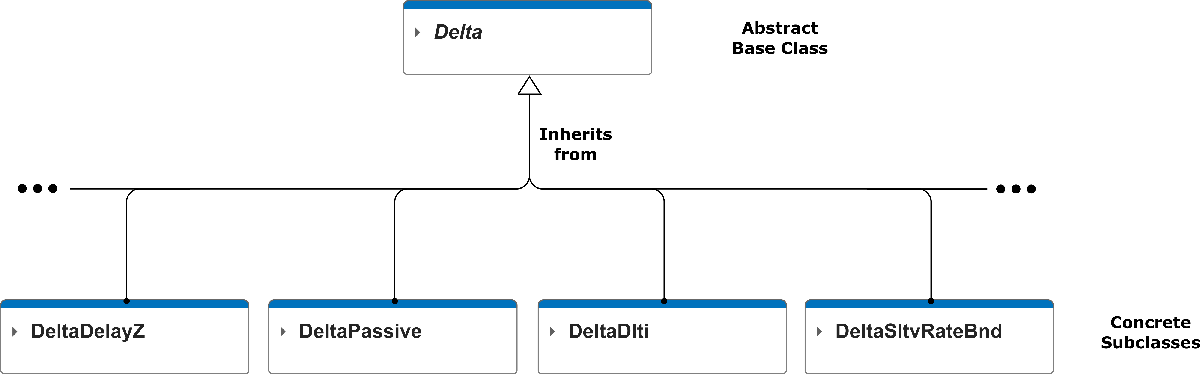

An abstract class cannot be instantiated:

% del = Delta('base_object', 1, 1, [0, 1]) % This will error because Delta is an abstract class

The purpose of the abstract `Delta` class is to provide the necessary properties and methods that all `Delta` subclasses will inherit, as well as force developers to concretize specific abstract methods which will be uniquely resolved by each subclass.  This allows the generation of novel subclasses while ensuring that each subclass has certain essential properties and methods that other classes (such as `Ulft)` and functions (such as `iqcAnalysis`) rely on.

There are numerous other abstract classes in `iqcToolbox` ( `MultiplierDelta`, `Performance`, `Disturbance`, etc.). This documentation will first focus on the `Delta` class, and then turn to the `MultiplierDelta` class.  Many of the same considerations of these two classes will apply for `Performance`, `MultiplierPerformance`, `Disturbance`, and `MultiplierDisturbance` classes. The following sections are intended to discuss the elements a developer should be aware of when developing a new `Delta` subclass, and similar observations can be made for `Performance` and `Disturbance` classes.

## Abstract `Delta` base class

As discussed in the previous section, every uncertainty/nonlinearity in `iqcToolbox` is a subclass of the abstract `Delta` class.  Here we discuss the properties and methods inherited from the `Delta` class, with particular attention on the abstract methods that must be overridden or concretized and the base methods that may be overridden.  The following graphic depicts how some `Delta` subclasses have extended the `Delta` class:

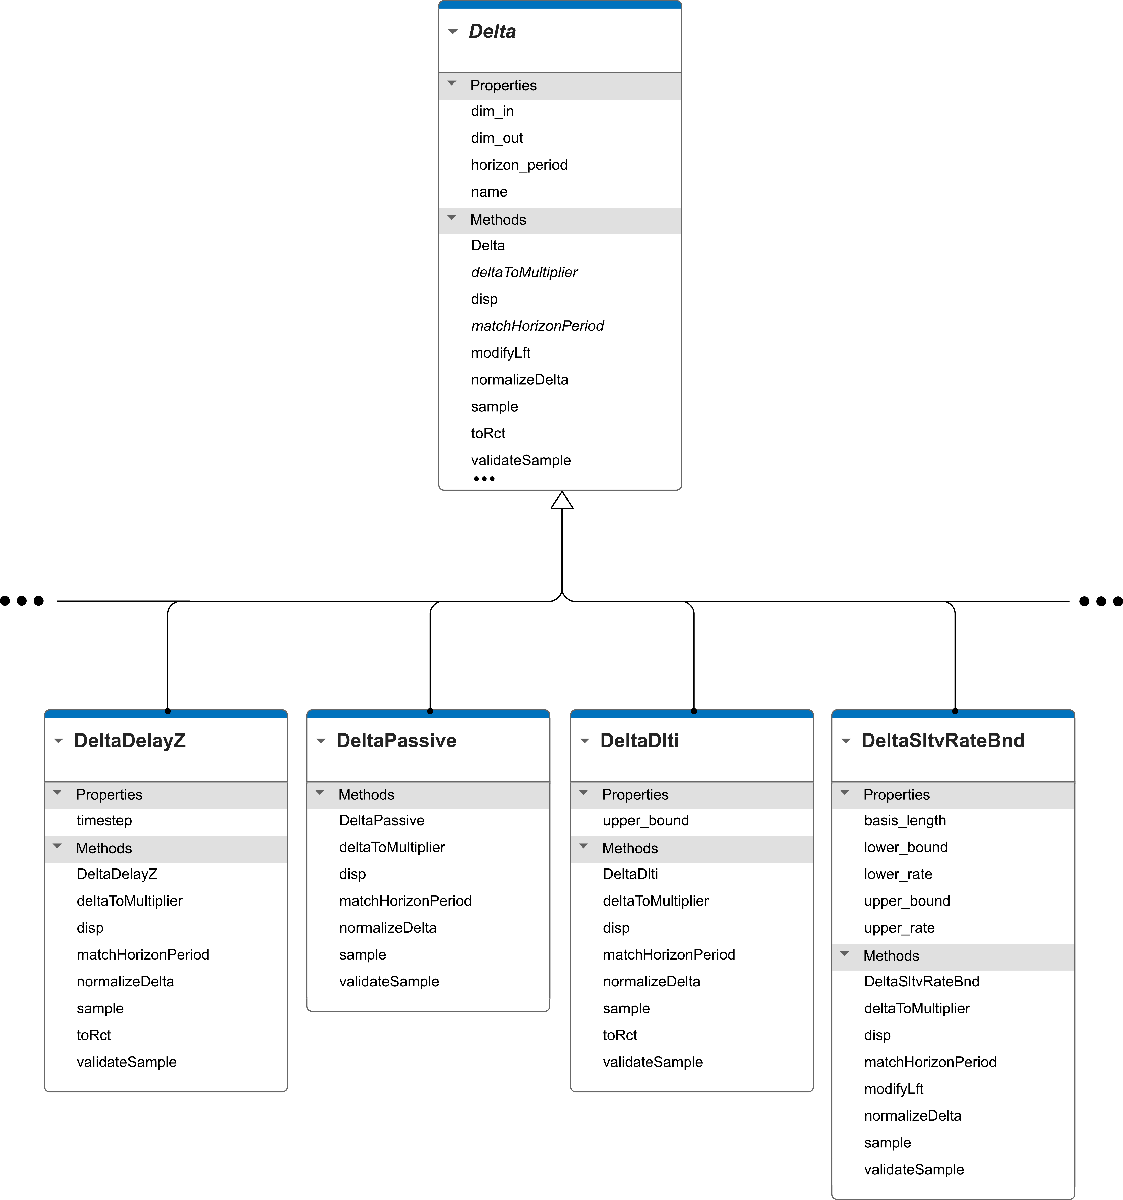

For example, `DeltaPassive` needs no additional properties beyond those from `Delta`. Such is not the case for any of the other listed subclasses.  Certain subclasses (`DeltaDelayZ` and `DeltaDlti)` override the `Delta.toRct` method, but while others (`DeltaPassive` and `DeltaSltvRateBnd`) do not.

### Properties

#### `dim_out` and `dim_in`

These two properties are self-explanatory. They specify the input/output dimensions of the `Delta` object.

#### name

The unique identifier of this `Delta` object.  

del_mass = DeltaSlti('mass');
del_mass.name

ans = 'mass'

Not only does this provide an identifier to users, it helps `Delta` "collectors" (formally, the `SequenceDelta` class) find and gather different appearances of the same `Delta` object into one term.

1 + del_mass

ans = A [ 0,  1]-eventually periodic LFT with   1 outputs,   1 inputs,   0 states, and
  1 uncertainties forming a   1 x   1 uncertainty block
********************************************************************************
**********************************   DELTAS   **********************************
     mass    is a   1 x 1     SLTI uncertainty 
              within the bounds: [-1.0, 1.0] 

1 + del_mass * del_mass

ans = A [ 0,  1]-eventually periodic LFT with   1 outputs,   1 inputs,   0 states, and
  1 uncertainties forming a   2 x   2 uncertainty block
********************************************************************************
**********************************   DELTAS   **********************************
     mass    is a   2 x 2     SLTI uncertainty 
              within the bounds: [-1.0, 1.0] 

Observe that in the last expression `del_mass` appeared twice but was listed only once as a `2 x 2` uncertainty in the resulting LFT. This is made possible by searching for all uncertainties that share the same `name` and gathering them together.

Such gathering can only occur if each same-named `Delta` is truly the same.

dim_outin = 1;
bnd1 = 1;
bnd2 = 2;
del_mass1 = DeltaSlti('mass', dim_outin, -bnd1, bnd1)

del_mass1 =      mass    is a   1 x 1     SLTI uncertainty 
              within the bounds: [-1.0, 1.0] 

del_mass2 = DeltaSlti('mass', dim_outin, -bnd2, bnd2)

del_mass2 =      mass    is a   1 x 1     SLTI uncertainty 
              within the bounds: [-2.0, 2.0] 

% del_mass1 + del_mass2 % This will error because del_mass1 and del_mass2 have the same name but different properties

Hence, the `name` property not only provides an identifier to users, but helps the backend appropriately group uncertainties.

#### `horizon_period`

If you are unfamiliar with the `horizon_period` property, see the `horizon_period` subsection in the "Modeling uncertain systems with the Ulft class" documentation.  

It's important to note that this field only expresses the `horizon_period` of properties that define the related *multiplier* for this uncertainty/nonlinearity.  It does NOT specify that the $\Delta$ operator itself is eventually periodic with the given `horizon_period`. For example, a `DeltaSltv` object might have a `horizon_period` of `[2, 3]`, because its upper bound has the following pattern:


$$\texttt{upper\_bound}: \matrix{&\mathrm{period}:3&\mathrm{period}:3& \ldots \cr
[ \underbrace{1, \ 2},  &  \overbrace{3, \ 3, \ 4}, & \overbrace{3, \ 3, \ 4}, & \ldots] \cr
\mathrm{horizon}:2&&&}$$


which could be leveraged in constructing a $(2, \ 3)$-eventually periodic IQC multiplier. However, the uncertainty represented by `DeltaSltv` is not necessarily $(2, \ 3)$-eventually periodic; the uncertainty may vary arbitrarily over each timestep as long it remains within its eventually-periodic bounds.

#### A note on introducing new properties for subclasses

When designing a new `Delta` subclass, any properties needed to describe the uncertainty/nonlinearity may be introduced.  Three guiding principles to consider:

First, **only the properties necessary to construct the related multiplier should be defined**. This helps users know which properties are definitive for the uncertainty/nonlinearity.

Second, **do not include properties that describe the related multiplier but do not describe the uncertainty/nonlinearity**.  For example, `DeltaDlti` has only the additional property `upper_bound`. Its related multiplier `MultiplierDlti `has many other properties (`basis_poles`, `basis_length`, etc.), which are descriptive of how `MultiplierDlti` characterizes `DeltaDlti`. New `Delta` subclasses should follow the same separation of information.

Third, **any properties which depend on other properties should be implemented as "dependent" properties**. For example, `DeltaSltvRepeated` may describe different admissible regions for a collection of different uncertain parameters. These regions could be described as boxes, or with vertices, or with ellipses.  The region data for all of these types is in the property `region_data`, while ellipse descriptions that parse that data for ellipses is found in the "dependent" property `ellipses`.  Following this structure keeps users from inadvertently providing conflicting information when multiple properties can both be specified and describe each other.

### Methods

As of v0.9.0, the abstract `Delta` class has 23 methods. Two must be overridden, two must be concretized, five may be overridden, and fourteen cannot be overridden.  Fortunately, MATLAB OOP error handling helps developers know what methods they must implement and what they cannot implement.

#### Methods that must be overridden by subclasses

The following two methods must be overriden by any `Delta` subclass. Notably, each method, when overridden, ought to call the `Delta` base class's original method.

`Constructor`** (**`Delta(...))`

The constructor method for each subclass must be provided. Every `Delta` subclass constructor follows the same procedure:

- Input arguments are parsed according to `nargin`, filling in defaults as necessary

- The base `Delta` class constructor is called: `this_delta@Delta(name, dim_out, dim_in, horizon_period)`

- Values of the subclass's extended properties are checked for consistency (for example, `lower_bound <= upper_bound` for subclasses that have both properties)

- Extended properties are set with the validated values

The base class constructor is called in order to avoid repeating validity checks for properties that are common across all `Delta` subclasses.

`disp(this_del)`

Without overriding this method, MATLAB will error when trying to display the subclass object to the user. The established procedure of this method should:

- Call the base method with a description of the subclass's type: `disp@Delta(this_delta, 'one line type description')`

- Print any additional information specific to this instance of the subclass (lower/upper bounds, etc.)

#### Abstract methods that must be concretized in subclasses

The following two methods are designated in the `Delta` base class as "abstract methods" (that is, methods without any implementation). Any subclass must implement these abstract methods in order for that subclass to be "concrete" (i.e., may be instantiated with a specific object).

`matchHorizonPeriod(this_del, new_horizon_period)`

This method is essential for ensuring each aspect of an LFT (its nominal system matrices, uncertainties/nonlinearities, disturbances, and perfomance) all have the same `horizon_period`. This method is also used to synchronize the `horizon_period` of two objects that have mismatching `horizon_period`, enabling operations between the two objects. For example:

dim_outin = 1;
hp1 = [1, 3];
del1 = DeltaPassive('del1', dim_outin, hp1)

del1 =      del1    is a   1 x 1   passive uncertainty 

hp2 = [2, 5];
del2 = DeltaPassive('del2', dim_outin, hp2)

del2 =      del2    is a   1 x 1   passive uncertainty 

del_sum = del1 + del2

del_sum = A [ 2, 15]-eventually periodic LFT with   1 outputs,   1 inputs,   0 states, and
  2 uncertainties forming a   2 x   2 uncertainty block
********************************************************************************
**********************************   DELTAS   **********************************
     del1    is a   1 x 1   passive uncertainty 
     del2    is a   1 x 1   passive uncertainty 

del_sum.horizon_period

ans =      2    15


The ability to produce an object that has a `horizon_period` consistent with the `horizon_period` of each constituent element depends on an implementation of `matchHorizonPeriod` for each constituent object.

For this method, the only consideration developers must address when implementing new `Delta` subclasses are the subclass's properties that rely on the `horizon_period`.  These are typically properties such as `dim_out`, `dim_in`, `upper_bound`, and so forth. Developers can find examples of `matchHorizonPeriod` in existing subclasses, but the generic procedure for the method is as follows:

- Get indices and `horizon_period` that are consistent with the current `horizon_period` and the desired `horizon_period `(e.g. `[indices, new_hp] = makeNewIndices(current_hp, desired_hp))`

- Set `horizon_period`-dependent properties to be consistent with new `horizon_period` (e.g. `this_del.dim_out = this_del.dim_out(indices)`)

When `matchHorizonPeriod` is not provided with a `horizon_period` input, the method is being used to check that each `horizon_period`-dependent property of the object is consistent with its own `horizon_period`. This can be implemented with simple `assert()` statements. Examples abound in the various `Delta` subclasses.

`deltaToMultiplier(this_del, varargin)`

This method essentially constructs the associated `MultiplierDelta` subclass object from the given `Delta` subclass object. It requires having the `MultiplierDelta` subclass and its constructor defined, and is implemented very easily:

`multiplier = MultiplierDeltaSubclass(this_del, varargin)`

*Note:*

*While a successful implementation of this method requires that the *`MultiplierDelta`* subclass and its constructor are defined, the *`deltaToMultiplier`* method only becomes necessary when wanting to conduct IQC analysis. Hence, it may be advantageous to implement a dummy stub for the method first (such as: *`error('this is not implemented yet')`*) to first finish the other methods and test instantiations of the new *`Delta`* subclass interacting with the *`Ulft`* class and other *`Delta`* subclasses. Once the other methods are established, development can turn to the *`MultiplierDelta`* subclass, its constructor, and calling that constructor in the *`deltaToMultiplier`* method.*

#### Methods that may be overridden by subclasses

These five methods are convenience methods that broaden the capabilities of `Delta` subclass objects.  Not all of them can be implemented for every `Delta` subclass, and the base class implementation essential does nothing or throws a "not implemented" error. Developers may override any of these methods, but it's not necessary for allowing their `Delta` subclass to access basic IQC analysis.

`modifyLft(this_delta)`

This method is only necessary for `Delta` subclasses that require modifying the containing LFT in order to conduct IQC analysis. A demonstration of this use case can be found in the `DeltaSltvRateBnd` and `DeltaSltvRateBndImpl` classes, where objects from the former class transform the parent LFT to have different [`a, c]` matrices and a `DeltaSltvRateBndImpl` object. A similar use case for the `Performance` class can be found in the `PerformanceStable` subclass.

This method is typically not used, and a developer would know by the nature of their uncertainty/nonlinearity if such a method needed to override the base method. The base `Delta` implementation returns an empty function handle to indicate that no modifications of the LFT need to occur.

`normalizeDelta(this_delta)`

This method is used to normalize bounds of `Delta` subclass objects that have `upper_bound` or `upper_bound`/`lower_bound` properties, such that the normalized `Delta` subclass objects have `upper_bound = 1` (and `lower_bound = -1` for objects that have a `lower_bound` property). The method returns transformation parameters that are used to modify the `a`, `b`, `c`, `d` matrices of a parent LFT such that an equivalent LFT can be represented with the normalized `Delta` subclass objects.

This method is only meaningful to `Delta` subclasses that have an `upper_bound` property (see, for example, `DeltaBounded` or `DeltaDlti`) or an `upper_bound` and `lower_bound` property (see, for example, `DeltaSlti` or `DeltaSltv`). The base `Delta` implementation returns values which indicate that no normalization was performed and throws a warning flag that no normalization occurred for the `Delta` object.

`toRct(this_delta)`

This method is used to transform a given `Delta` subclass object into an uncertainty object in the Robust Control Toolbox package. Given the comparatively limited scope of uncertainties that can be treated in the Robust Control Toolbox, `toRct` can only be overridden by `DeltaSlti` and `DeltaDlti` classes. All other uncertainties/nonlinearities represented as `Delta` subclasses rely on the base `Delta` class implementation: create a placeholder `udyn` object with the same name as that from the `Delta` subclass object. However, in case of unforeseen changes in Robust Control Toolbox, this method may be overridden in future `Delta` subclasses.

`sample(this_delta, timestep)`

This method randomly samples a system that satisfies the characteristics of the uncertainty/nonlinearity set described by `this_delta`. The sample is a state-space system expressed as a `Ulft` object, so for many `Delta` subclass objects (especially ones specifying nonlinearities) the permissible sample set will not widely cover the set described by `this_delta`. In some cases, this function will not be able to return any state-space system that resides in the set described by `this_delta`. The base `Delta` class implementation simply throws an error saying that this method has not been developed for the `Delta` subclass.

The `timestep` parameter describes if `this_delta` is an operator in continuous or discrete time.  For example, an uncertain delay can have a state-space representation in discrete time, but not in continuous time. See `DeltaConstantDelay2` and `DeltaSltv` for examples of `sample()` that do and do not rely on the `timestep` parameter (respectively).

`validateSample(this_delta, value, timestep)`

This method takes a state-space system `value` (expressed as a `Ulft` object) and determines if it lies within the set described by `this_delta`. The base `Delta` class implementation checks that the properties of `value` are consistent with the properties of the base `Delta` class. This can be extended in each subclass, and it is suggested that any overridding method calls that base method. Similar to the `sample()` method, `validateSample()` will need the `Ulft.timestep` information for certain `Delta` subclasses.

#### Methods that may not be overridden by subclasses

The remaining methods of the `Delta` class are not allowed to be overridden.  They allow MATLAB to treat any `Delta` object as a `Ulft` object for various operations (addition, multiplication, etc.).  They should be of no concern to the developer.

## `SequenceDelta` class

As discussed at the beginning of this documentation, an LFT has at least one, usually many, different types of uncertainties/nonlinearities that are structured block diagonally to represent the $\Delta$block. The `SequenceDelta` class provides consistency checking and basic backend management of the various `Delta` objects that represent the different uncertainties, nonlinearities and operators in $\Delta$. 

IMAGE

Consider the `SequenceDelta` class as a glorified cell array class that provides convenient handles and basic processing for each element in its array. It should mostly be invisible to the user, and is only discussed here to preempt any questions from the developer.

Any `Ulft` object contains a `SequenceDelta` object, which contains all the `Delta` objects for the LFT:

g_lft = Ulft.random('num_deltas', 4)

g_lft = A [ 0,  1]-eventually periodic LFT with   5 outputs,   6 inputs,   7 states, and
  3 uncertainties forming a  19 x  25 uncertainty block
********************************************************************************
**********************************   DELTAS   **********************************
     DelayZ  is a   7 x 7       delay operator 
              with a timestep of 1.4e-01 seconds 
     BnvDSPmDxW is a   5 x 5   SLTV, rate-bounded uncertainty 
              within the bounds: [-3.6, 3.6] 
              whose rate-of-change is within: [-4.1, 4.1] 
     PZuPHoUgIT is a  10 x 10    SLTV uncertainty 
              within the bounds: [-8.1, 8.1] 
     hNOlRgRxvr is a   4 x 10  l2 norm-bounded uncertainty 
              with an l2-induced norm less than: 2.1 

class(g_lft.delta)

ans = 'SequenceDelta'

g_lft.delta

ans = ********************************************************************************
**********************************   DELTAS   **********************************
     DelayZ  is a   7 x 7       delay operator 
              with a timestep of 1.4e-01 seconds 
     BnvDSPmDxW is a   5 x 5   SLTV, rate-bounded uncertainty 
              within the bounds: [-3.6, 3.6] 
              whose rate-of-change is within: [-4.1, 4.1] 
     PZuPHoUgIT is a  10 x 10    SLTV uncertainty 
              within the bounds: [-8.1, 8.1] 
     hNOlRgRxvr is a   4 x 10  l2 norm-bounded uncertainty 
              with an l2-induced norm less than: 2.1 

properties(g_lft.delta)

Properties for class SequenceDelta:

    deltas
    dim_outs
    dim_ins
    horizon_periods
    names
    types



g_lft.delta.deltas{1}

ans =      DelayZ  is a   7 x 7       delay operator 
              with a timestep of 1.4e-01 seconds 

The central property of a `SequenceDelta` object is `deltas`, a standard cell array of `Delta` objects.  All other properties (`names`, `types`, `dim_outs`, etc.) are for convenience and depend on the `deltas` property. The `SequenceDelta` object also makes basic consistency checks among `Delta` objects in its cell array.

integrator = DeltaIntegrator; % continuous-time state evolution operator
delay = DeltaDelayZ; % discrete-time state evolution operator
% SequenceDelta(integrator, delay) % this will error, cannot combine discrete-time with continuous-time elements

Developers should not be concerned with modifying this class.

## `MultiplierDelta` classes

In `iqcToolbox`, the modeling aspects and the analysis aspects are well separated.  One can model an uncertain/nonlinear system with a `Ulft` object that contains various `Delta` objects, and then easily manipulate/inspect/sample that system. However, `Delta` classes are not sufficient for conducting IQC *analysis* on the system.  The ability to leverage IQCs for an uncertain system depends on `MultiplierDelta` classes, which express how such `Delta` classes can be characterized for IQC analysis. In other words, `Delta` classes provide all the information to describe an uncertainty/nonlinearity set, while `MultiplierDelta` classes describe how that set will be characterized in an analytic framework.

The connection between these two classes exists in the `Delta.deltaToMultiplier` method and the `MultiplierDelta` constructor method, each of which must be defined by the developer

explain they are actually arrays (cell vs. array access)

### Abstract `MultiplierDelta` base class

#### Properties

#### Methods

#### Implementing your constructor

### Exponential IQCs

## Conclusion